% === Configuração do ROS ===
% === Configuração do ROS ===
clc; close all;
% setenv('ROS_MASTER_URI','http://192.168.245.132:11311');
% setenv('ROS_IP','192.168.187.128');
rosshutdown;
rosinit('192.168.187.128', 11311);

The value of the ROS_IP environment variable, 192.168.245.1, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_34954 with NodeURI http://192.168.245.1:51231/ and MasterURI http://192.168.187.128:11311.


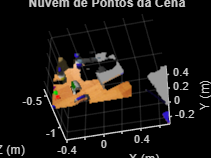

% === Captura da nuvem de pontos do sensor ===
pcSub = rossubscriber('/camera/depth/points', 'sensor_msgs/PointCloud2', 'DataFormat', 'struct');
pause(1);
pcMsg = receive(pcSub, 3);

% Extrai XYZ
xyz = rosReadXYZ(pcMsg, "PreserveStructureOnRead", true);
xyzVec = reshape(xyz, [], 3);

% Extrai RGB (opcional)
try
    rgb = rosReadRGB(pcMsg, "PreserveStructureOnRead", true);
    rgbVec = reshape(rgb, [], 3);
    hasColor = true;
catch
    hasColor = false;
end

% Remove NaNs
valid = ~any(isnan(xyzVec), 2);
xyzClean = xyzVec(valid, :);
xyzClean(:,3) = -xyzClean(:,3);  % Inverte o eixo Z para alinhar com câmera

% Cria ptCloud da cena
if hasColor
    rgbClean = uint8(255 * rgbVec(valid, :));
    ptCena = pointCloud(xyzClean, "Color", rgbClean);
else
    ptCena = pointCloud(xyzClean);
end

% Mostrar cena
figure;
pcshow(ptCena, VerticalAxis="Y", VerticalAxisDir="Up");
title("Nuvem de Pontos da Cena");
xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");

% === Carregar o detector treinado ===
data = load("C:\Users\roboime\Desktop\Detectores.mat", "detector");
detector = data.detector;

% === Aplicar o detector ===
[bboxes, scores, labels] = detect(detector, ptCena, Threshold=0.3);

% === Exibir resultados ===
fprintf("Número de detecções: %d\n", size(bboxes,1));

Número de detecções: 0


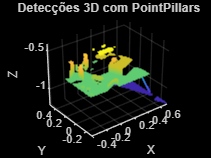

for i = 1:size(bboxes,1)
    pos = bboxes(i,1:3);   % [x y z]
    dims = bboxes(i,4:6);  % [length width height]
    yaw  = bboxes(i,9);    % orientação (rad)
    conf = scores(i);      % confiança [0-1]

    fprintf("Detecção %d:\n", i);
    fprintf(" - Classe     : %s\n", string(labels(i)));
    fprintf(" - Confiança  : %.2f%%\n", conf*100);
    fprintf(" - Centro     : [x=%.2f, y=%.2f, z=%.2f]\n", pos);
    fprintf(" - Dimensões  : [L=%.2f, W=%.2f, H=%.2f]\n", dims);
    fprintf(" - Orientação : %.2f°\n\n", rad2deg(yaw));
end

% === Visualizar a nuvem e as detecções ===
figure;
ax = pcshow(ptCena.Location, 'VerticalAxis','Z','VerticalAxisDir','Up');
title("Detecções 3D com PointPillars");
xlabel('X'); ylabel('Y'); zlabel('Z');
hold on;


if ~isempty(bboxes)
    showShape("cuboid", bboxes, Parent=ax, Color="green", Opacity=0.3, LineWidth=1);
end

% Após executar a detecção [bboxes, scores, labels]
pcObjs = {};  % lista para armazenar pointClouds por objeto detectado

for i = 1:size(bboxes,1)
    ctr = bboxes(i,1:3);
    dims = bboxes(i,4:6);
    yaw  = bboxes(i,9);
    % Calcula ROI axis-aligned simples (tipo caixa englobante):
    half = dims/2;
    xmin = ctr(1) - half(1);
    xmax = ctr(1) + half(1);
    ymin = ctr(2) - half(2);
    ymax = ctr(2) + half(2);
    zmin = ctr(3) - half(3);
    zmax = ctr(3) + half(3);
    roi = [xmin xmax ymin ymax zmin zmax];
    idx = findPointsInROI(ptCloud, roi);
    % Cria e armazena pointCloud apenas do objeto
    objPC = select(ptCloud, idx);
    pcObjs{end+1} = objPC;
    
    % Visualização opcional:
    figure;
    pcshow(objPC);
    title(sprintf("Objeto detectado %d: %s", i, string(labels(i))));
end

% % ==Importar modelo superfície==
% % Leitura do STL
% meshData = stlread("C:\Users\pecci\OneDrive\Desktop\Modelos_garra\canYellow.stl");
% %meshData = stlread("C:\Users\pecci\OneDrive\Desktop\Modelos_garra\bottle.stl");
% % Detectar o tipo de retorno
% if isa(meshData, "triangulation")
%     % Já está no formato correto
%     tri = meshData;
% 
% elseif isstruct(meshData) && all(isfield(meshData, ["Points", "ConnectivityList"]))
%     % Estrutura retornada por stlread moderno
%     tri = triangulation(meshData.ConnectivityList, meshData.Points);
% 
% elseif iscell(meshData)
%     % Se for uma célula: [faces, vertices] = stlread(...)
%     [faces, vertices] = meshData{:};
%     tri = triangulation(faces, vertices);
% 
% else
%     error("Formato de saída de stlread não reconhecido.");
% end
% 
% % Gerar nuvem de pontos com mesh2pc
% ptModelo = mesh2pc(tri, ...
%     NumPoints=5000, ...
%     SamplingMethod="PoissonDiskSampling");
% 
% %correção de escala
% scaleFactor = 0.034;% Fator de escala
% ptCloudScaled = pointCloud(ptModelo.Location * scaleFactor);
% if ~isempty(ptModelo.Normal)% Preservar as normais, se existirem
%     ptCloudScaled.Normal = ptModelo.Normal;
% end
% 
% % Visualização
% figure('Name','Nuvem de Pontos da Malha STL','Color','w');
% pcshow(ptCena, 'MarkerSize', 30);
% title('Nuvem de Pontos do Modelo STL');
% xlabel('X'); ylabel('Y'); zlabel('Z');
% axis equal; grid on;
% view(3);

% % Supondo que você já tenha:
% % segmentPC = pointCloud do segmento detectado
% % modelPC   = pointCloud do modelo completo
% 
% % 1. Opcional: downsample para ganhar performance
% gridSize = 0.01;  % ajustar conforme resolução
% segmentDS = pcdownsample(segmentPC, "gridAverage", gridSize);
% modelDS   = pcdownsample(modelPC,   "gridAverage", gridSize);
% 
% % 2. Registrar com ICP
% [tform, segmentReg, rmse] = pcregistericp(segmentDS, modelDS, ...
%     Metric="pointToPlane", MaxIterations=50, Tolerance=[0.005, 0.005]);
% 
% % 3. Exibir resultado
% fprintf("ICP final RMSE = %.4f\n", rmse);
% 
% % 4. Extração da translação e rotação
% A = tform.A;  % matriz 4x4
% rotationMatrix = A(1:3,1:3);
% translationVec = A(4,1:3);
% 
% yaw  = atan2(rotationMatrix(2,1), rotationMatrix(1,1));
% pitch= atan2(-rotationMatrix(3,1), ...
%              sqrt(rotationMatrix(3,2)^2 + rotationMatrix(3,3)^2));
% roll = atan2(rotationMatrix(3,2), rotationMatrix(3,3));
% 
% fprintf("Translação (X,Y,Z): [%.3f, %.3f, %.3f]\n", translationVec);
% fprintf("Rotação (roll,pitch,yaw em graus): [%.1f°, %.1f°, %.1f°]\n", ...
%     rad2deg([roll, pitch, yaw]));
% 
% % 5. Visualização
% figure;
% pcshowpair(segmentReg, modelPC, 'MarkerSize', 50);
% title('Segmento Registrado vs Modelo Completo');
% legend('Segmento (após registro)','Modelo completo');

% % --- 1. Extrai centro do segmento no sensor --- 
% posSegmentSensor = bboxes(i,1:3);  % [x y z] em relação ao sensor
% 
% % --- 2. Uso do ICP para alinhar ao modelo completo ---
% [tform, ~, rmse] = pcregistericp(segmentDS, modelDS, ...
%     Metric="pointToPlane", MaxIterations=50);
% A = tform.A;
% posSegment2Model = A(4,1:3);  % translação do segmento em relação ao modelo
% 
% % --- 3. Computa posição do modelo no referencial do sensor ---
% posModelSensor = posSegmentSensor + posSegment2Model;
% 
% % --- 4. Ajusta posição para o plano fixo (referencial global) ---
% posGarra = [x_g; y_g; z_g];  % posição conhecida da garra
% posObjetoPlano = posModelSensor + posGarra;
% 
% fprintf("Posição do objeto (referencial global, plano fixo): [%.3f, %.3f, %.3f] m\n", ...
%     posObjetoPlano);
% 
% % --- Extras: extração de orientação (Euler angles) ---
% R = A(1:3,1:3);
% yaw   = atan2(R(2,1), R(1,1));
% pitch = atan2(-R(3,1), sqrt(R(3,2)^2 + R(3,3)^2));
% roll  = atan2(R(3,2), R(3,3));
% fprintf("Orientação: roll=%.1f°, pitch=%.1f°, yaw=%.1f°\n", ...
%     rad2deg([roll,pitch,yaw]));
